
clc
clear
close
core = zeros(43, 2);
ber = zeros(40, 1);
db = zeros(40, 1);
input = randsrc(1000000, 4, [0 1])

input =      1     1     1     0
     0     1     1     0
     1     1     1     0
     1     1     0     0
     1     0     1     1
     0     1     0     1
     1     0     1     0
     0     1     0     1
     1     0     0     1
     0     1     0     0


k = 1

k = 1

for Esav = 10 : 30 : 730
    Esav
    for i = 1: 5000
        m = input(i,1:4);
        a = Sixteen_QAM(m, Esav);
        b = AWGN_channel(a, 2);
        c = ML_demodulation(b, Esav);
        core(k,1:2) = core(k, 1:2) + BER_analysis(m, c);
    end
    ber(k,1) = core(k,2)/(core(k,1) + core(k,2));
    db(k,1) = 10*log10(Esav/4/8);
    k = k + 1;   
end

Esav = 10

Esav = 40

Esav = 70

Esav = 100

Esav = 130

Esav = 160

Esav = 190

Esav = 220

Esav = 250

Esav = 280

Esav = 310

Esav = 340

Esav = 370

Esav = 400

Esav = 430

Esav = 460

Esav = 490

Esav = 520

Esav = 550

Esav = 580

Esav = 610

Esav = 640

Esav = 670

Esav = 700

Esav = 730

ber

ber =     0.2626
    0.1173
    0.0684
    0.0422
    0.0283
    0.0174
    0.0103
    0.0066
    0.0040
    0.0033


db

db =    -5.0515
    0.9691
    3.3995
    4.9485
    6.0879
    6.9897
    7.7360
    8.3727
    8.9279
    9.4201


ebofNodb=-2:0.001:14

ebofNodb =    -2.0000   -1.9990   -1.9980   -1.9970   -1.9960   -1.9950   -1.9940   -1.9930   -1.9920   -1.9910   -1.9900   -1.9890   -1.9880   -1.9870   -1.9860   -1.9850   -1.9840   -1.9830   -1.9820   -1.9810   -1.9800   -1.9790   -1.9780   -1.9770   -1.9760   -1.9750   -1.9740   -1.9730   -1.9720   -1.9710   -1.9700   -1.9690   -1.9680   -1.9670   -1.9660   -1.9650   -1.9640   -1.9630   -1.9620   -1.9610   -1.9600   -1.9590   -1.9580   -1.9570   -1.9560   -1.9550   -1.9540   -1.9530   -1.9520   -1.9510


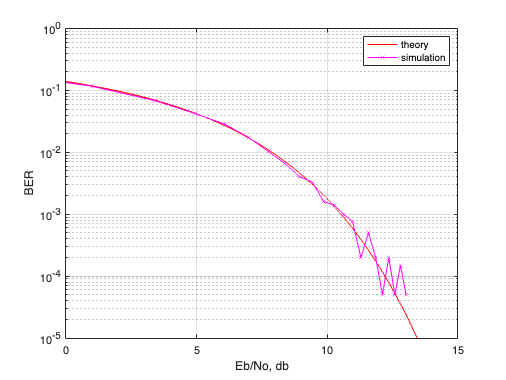

figure(1), semilogy(ebofNodb, 1*(3/4)*qfunc(sqrt((3*4/15)*10.^(ebofNodb/10))), 'r-');
hold on
axis([0 15 10^-5 1])
grid on
semilogy(db, ber, 'mx-')
legend('theory', 'simulation')
xlabel('Eb/No, db')
ylabel('BER')

clc
clear
close
core = zeros(1, 2);
Esav = 320;
ber = zeros(10, 1);
db = zeros(10, 1);
k = 1;
for i = 1: 10000
    m = [0 0 0 0];
    a = Sixteen_QAM(m, Esav);
    b = AWGN_channel(a, 2);
    c = ML_demodulation(b, Esav);
    core = core + BER_analysis(m, c);
end
ber = core(2)/(core(1)+core(2))

ber = 0.0027

db = 10*log10(Esav/4/8)

db = 10

m = randsrc(1, 4, [0 1])

m =      0     1     1     1


a = Sixteen_QAM(m, Esav)

a =    16.9706  -16.9706


b = AWGN_channel(a, 2)

b =    18.2854  -15.4950


c = ML_demodulation(b, Esav)

c =      0     1     1     1


clc
clear
binVal = de2bi(0:63, 6, 'left-msb')  % path metric 계산을 위한 계산

binVal =      0     0     0     0     0     0
     0     0     0     0     0     1
     0     0     0     0     1     0
     0     0     0     0     1     1
     0     0     0     1     0     0
     0     0     0     1     0     1
     0     0     0     1     1     0
     0     0     0     1     1     1
     0     0     1     0     0     0
     0     0     1     0     0     1


output0 = zeros(64,2);
output1 = zeros(64,2);
for i = 1:64
    output0(i,:) = Convolution_code_not_tail(0, binVal(i,1:6));
    output1(i,:) = Convolution_code_not_tail(1, binVal(i,1:6));
end

     0
     0
     0
     0
     0
     0



     1
     0
     0
     0
     0
     0



     0
     0
     0
     0
     0
     0



     1
     0
     0
     0
     0
     0



     0
     0
     0
     0
     0
     1



     1
     0
     0
     0
     0
     1



     0
     0
     0
     0
     0
     1



     1
     0
     0
     0
     0
     1



     0
     0
     0
     0
     1
     0



     1
     0
     0
     0
     1
     0



     0
     0
     0
     0
     1
     0



     1
     0
     0
     0
     1
     0



     0
     0
     0
     0
     1
     1



     1
     0
     0
     0
     1
     1



     0
     0
     0
     0
     1
     1



     1
     0
     0
     0
     1
     1



     0
     0
     0
     1
     0
     0



     1
     0
     0
     1
     0
     0



     0
     0
     0
     1
     0
     0



     1
     0
     0
     1
     0
     0



     0
     0
     0
     1
     0
     1



     1
     0
     0
     1
     0
     1



     0
     0
     0
     1
     0
     1



     1
     0
     0
     1
     0
     1



     0
     0
     0
     1
     1
     0



     1
     0
     0
     1
     1
     0



     0
     0
     0
     1
     1
     0



     1
     0
     0
     1
     1
     0



     0
     0
     0
     1
     1
     1



     1
     0
     0
     1
     1
     1



     0
     0
     0
     1
     1
     1



     1
     0
     0
     1
     1
     1



     0
     0
     1
     0
     0
     0



     1
     0
     1
     0
     0
     0



     0
     0
     1
     0
     0
     0



     1
     0
     1
     0
     0
     0



     0
     0
     1
     0
     0
     1



     1
     0
     1
     0
     0
     1



     0
     0
     1
     0
     0
     1



     1
     0
     1
     0
     0
     1



     0
     0
     1
     0
     1
     0



     1
     0
     1
     0
     1
     0



     0
     0
     1
     0
     1
     0



     1
     0
     1
     0
     1
     0



     0
     0
     1
     0
     1
     1



     1
     0
     1
     0
     1
     1



     0
     0
     1
     0
     1
     1



     1
     0
     1
     0
     1
     1



     0
     0
     1
     1
     0
     0



     1
     0
     1
     1
     0
     0



     0
     0
     1
     1
     0
     0



     1
     0
     1
     1
     0
     0



     0
     0
     1
     1
     0
     1



     1
     0
     1
     1
     0
     1



     0
     0
     1
     1
     0
     1



     1
     0
     1
     1
     0
     1



     0
     0
     1
     1
     1
     0



     1
     0
     1
     1
     1
     0



     0
     0
     1
     1
     1
     0



     1
     0
     1
     1
     1
     0



     0
     0
     1
     1
     1
     1



     1
     0
     1
     1
     1
     1



     0
     0
     1
     1
     1
     1



     1
     0
     1
     1
     1
     1



     0
     1
     0
     0
     0
     0



     1
     1
     0
     0
     0
     0



     0
     1
     0
     0
     0
     0



     1
     1
     0
     0
     0
     0



     0
     1
     0
     0
     0
     1



     1
     1
     0
     0
     0
     1



     0
     1
     0
     0
     0
     1



     1
     1
     0
     0
     0
     1



     0
     1
     0
     0
     1
     0



     1
     1
     0
     0
     1
     0



     0
     1
     0
     0
     1
     0



     1
     1
     0
     0
     1
     0



     0
     1
     0
     0
     1
     1



     1
     1
     0
     0
     1
     1



     0
     1
     0
     0
     1
     1



     1
     1
     0
     0
     1
     1



     0
     1
     0
     1
     0
     0



     1
     1
     0
     1
     0
     0



     0
     1
     0
     1
     0
     0



     1
     1
     0
     1
     0
     0



     0
     1
     0
     1
     0
     1



     1
     1
     0
     1
     0
     1



     0
     1
     0
     1
     0
     1



     1
     1
     0
     1
     0
     1



     0
     1
     0
     1
     1
     0



     1
     1
     0
     1
     1
     0



     0
     1
     0
     1
     1
     0



     1
     1
     0
     1
     1
     0



     0
     1
     0
     1
     1
     1



     1
     1
     0
     1
     1
     1



     0
     1
     0
     1
     1
     1



     1
     1
     0
     1
     1
     1



     0
     1
     1
     0
     0
     0



     1
     1
     1
     0
     0
     0



     0
     1
     1
     0
     0
     0



     1
     1
     1
     0
     0
     0



     0
     1
     1
     0
     0
     1



     1
     1
     1
     0
     0
     1



     0
     1
     1
     0
     0
     1



     1
     1
     1
     0
     0
     1



     0
     1
     1
     0
     1
     0



     1
     1
     1
     0
     1
     0



     0
     1
     1
     0
     1
     0



     1
     1
     1
     0
     1
     0



     0
     1
     1
     0
     1
     1



     1
     1
     1
     0
     1
     1



     0
     1
     1
     0
     1
     1



     1
     1
     1
     0
     1
     1



     0
     1
     1
     1
     0
     0



     1
     1
     1
     1
     0
     0



     0
     1
     1
     1
     0
     0



     1
     1
     1
     1
     0
     0



     0
     1
     1
     1
     0
     1



     1
     1
     1
     1
     0
     1



     0
     1
     1
     1
     0
     1



     1
     1
     1
     1
     0
     1



     0
     1
     1
     1
     1
     0



     1
     1
     1
     1
     1
     0



     0
     1
     1
     1
     1
     0



     1
     1
     1
     1
     1
     0



     0
     1
     1
     1
     1
     1



     1
     1
     1
     1
     1
     1



     0
     1
     1
     1
     1
     1



     1
     1
     1
     1
     1
     1



input = randsrc(1, 96, [0 1])

input =      0     0     0     0     1     1     1     1     0     0     1     1     1     0     1     1     1     0     0     0     0     0     1     1     0     1     1     0     1     0     1     1     1     0     1     1     0     0     1     0     1     0     1     1     1     1     0     1     1     1


encoded_input = Convolution_code_tail_bit(input)

encoded_input =      0     0     0     0     0     0     0     0     1     1     0     1     1     0     0     1     1     0     0     1     1     0     1     1     0     0     0     1     1     1     1     1     0     0     0     0     1     1     1     0     1     0     1     0     0     0     0     1     0     1


decoding = Viterbi_decoding(encoded_input, 96)

     0
     0
     0
     0
     0
     0

     1
     0
     0
     0
     0
     0

     0
     0
     0
     0
     0
     0

     1
     0
     0
     0
     0
     0

